## Group Homework 4

Amanda Chang, Dokyun Kim, Jun Park

**1. Frequency domain filtering.** Do the following for 2 images of your choice **(10 points each for all sub-parts = 30 points total)**

- Apply low pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Apply high pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Add noise to your images. Does spatial domain filtering (median filtering, spatial domain gauss filter, etc.) work better to remove this noise or frequency domain filtering? 

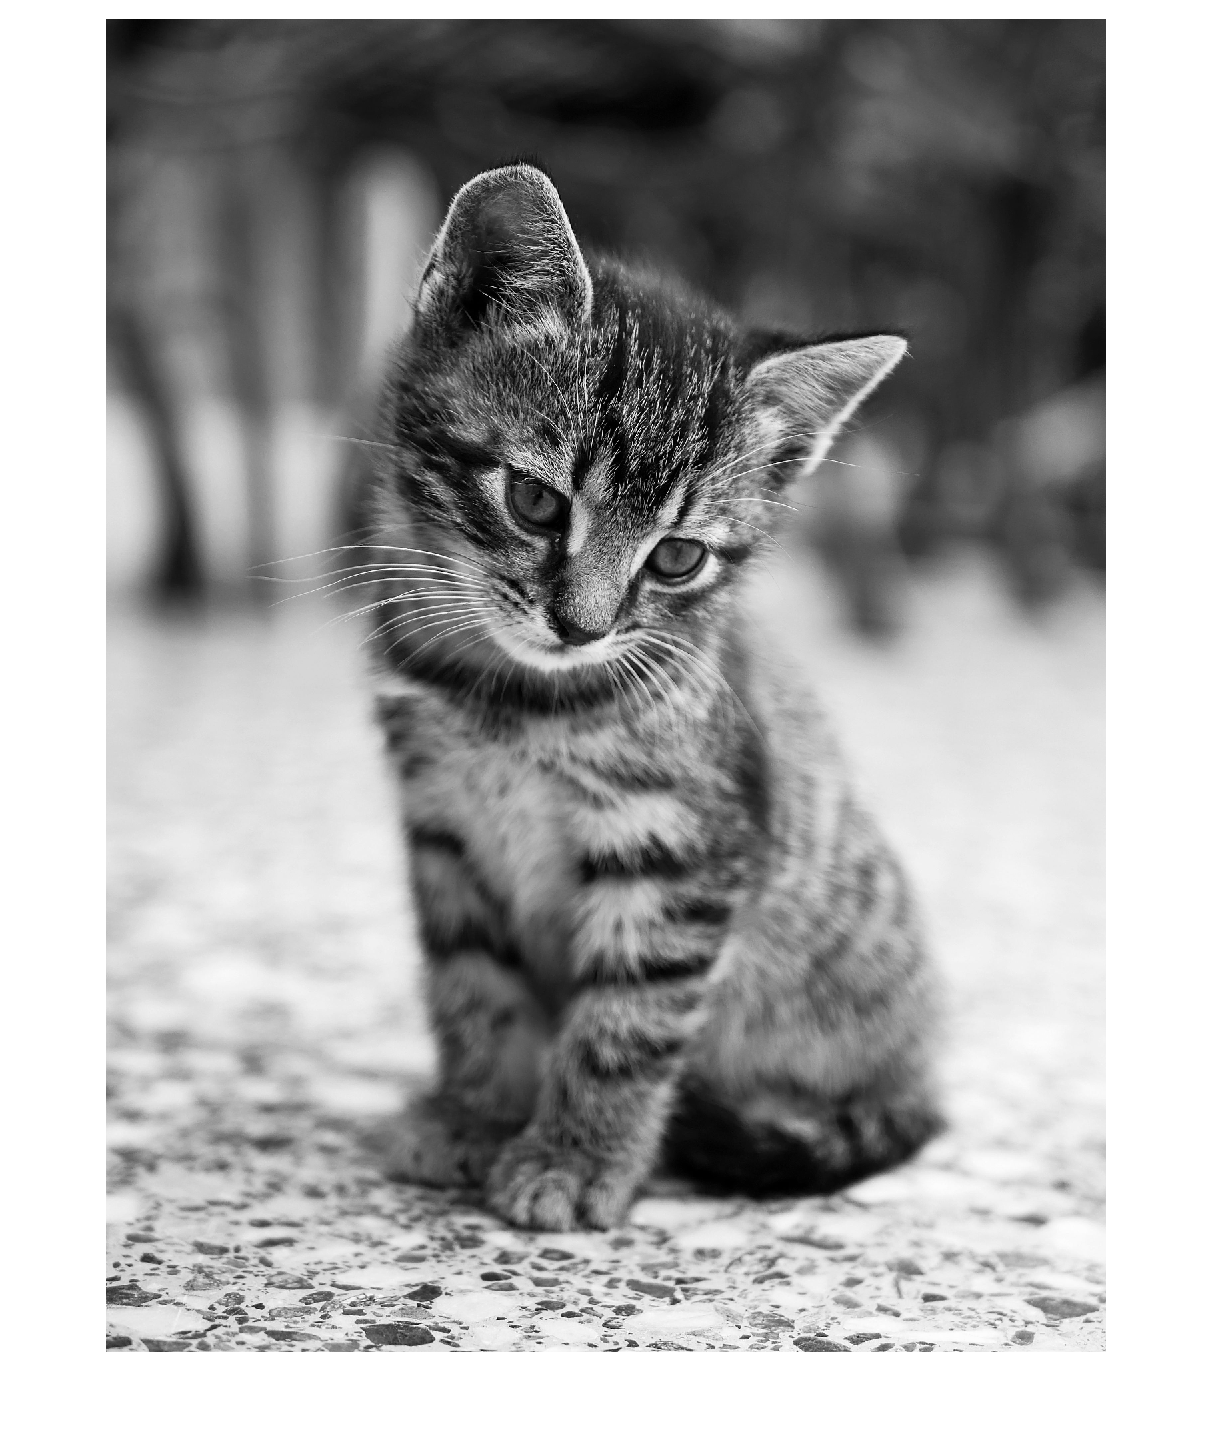

clear all;
close all;

img1 = rgb2gray(imread("../../pictures/cat.jpeg"));
img2 = rgb2gray(imread("../../pictures/dog.png"));
I1 = fftshift(fft2(img1));
I2 = fftshift(fft2(img2));

figure();
imshow(img1);

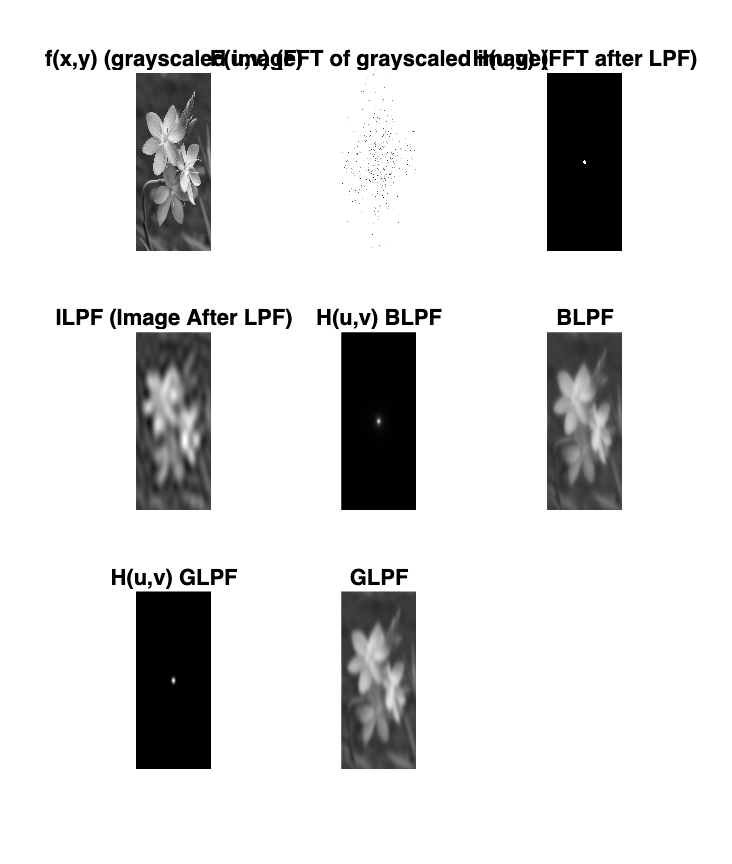

title("Original Image 1");

figure();
imshow(img2);
title("Original Image 2");

###  Low pass filter

LPF1 = make_filter(I1, 100, 'lowpass');

Unrecognized function or variable 'f'.

Error in main>make_filter (line 272)
        filter = double(distance <= radius);f

LPF2 = make_filter(I2, 20, 'lowpass');

I1_LPF = (ifft2(I1 .* LPF1));
I2_LPF = (ifft2(I2 .* LPF2));

figure();
imshow(real(I1_LPF), []);
title('Low-Pass Filtered Image 1');

figure();
imshow(real(I2_LPF), []);
title('Low-Pass Filtered Image 2');

### High pass filter

HPF1 = make_filter(I1, 100, 'highpass');
HPF2 = make_filter(I2, 20, 'highpass');

I1_HPF = (ifft2(I1 .* HPF1));
I2_HPF = (ifft2(I2 .* HPF2));

figure();
imshow(real(I1_HPF), []);
title('High-Pass Filtered Image 1');
figure();
imshow(real(I2_HPF), []);
title('High-Pass Filtered Image 2');

### Spatial filter vs. Frequency filter

noised1 = imnoise(img1, 'gaussian', 0, 0.01);
noised2 = imnoise(img2, 'gaussian', 0, 0.01);
N1 = fftshift(fft2(noised1));
N2 = fftshift(fft2(noised2));

% Display noisy images
figure();
imshow(noised1);
title('Noisy Image 1');
figure();
imshow(noised2);
title('Noisy Image 2');

% Apply spatial filtering

#### Apply Spatial Filters (Median & Gaussian)

medfilt_1 = medfilt2(noised1);
medfilt_2 = medfilt2(noised2);
gausfilt_1 = imgaussfilt(noised1);
gausfilt_2 = imgaussfilt(noised2);

figure();
imshow(medfilt_1);
title('Median Filtered Image 1');
figure();
imshow(medfilt_2);
title('Median Filtered Image 2');
figure();
imshow(gausfilt_1);
title('Gaussian Filtered Image 1');
figure();
imshow(gausfilt_2);
title('Gaussian Filtered Image 2');

#### Apply Frequency Domain Filters (Low Pass & High Pass)

LPF1 = make_filter(N1, 300, 'lowpass');
LPF2 = make_filter(N2, 100, 'lowpass');
HPF1 = make_filter(N1, 100, 'highpass');
HPF2 = make_filter(N2, 20, 'highpass');

N1_LPF = (ifft2(N1 .* LPF1));
N2_LPF = (ifft2(N2 .* LPF2));
N1_HPF = (ifft2(N1 .* HPF1));
N2_HPF = (ifft2(N2 .* HPF2));

figure();
imshow(real(N1_LPF), []);
title('Low-Pass Filtered Noisy Image 1');

figure();
imshow(real(N2_LPF), []);
title('Low-Pass Filtered Noisy Image 2');

figure();
imshow(real(N1_HPF), []);
title('High-Pass Filtered Noisy Image 1');
figure();
imshow(real(N2_HPF), []);
title('High-Pass Filtered Noisy Image 2');

For Gaussian Noise, spatial filters seem to perform better than frequency domain filters when it comes to denoising the image. Low-pass filters does remove noise but the image also loses some features. High-pass filters end up making the image more noisy.

**2. Deconvolution and Deblurring. **MATLAB and other programming platforms allow you to do a blind deconvolution or use some pre-designed functions to achieve deblurring. Try out the given sample code [trydeconv.m](https://canvas.olin.edu/courses/819/files/186973?wrap=1)[ ](https://canvas.olin.edu/courses/819/files/186973/download?download_frd=1)on some of your images. What are the pros and cons of these pre-designed functions? Pre-designed functions estimate the blurring kernel for you. Research and explain any two methods of estimating a deblurring kernel without using pre-designed functions? You can use any material available to do your research – youtube videos, research papers, tutorials – whatever your group chooses. **(30 points).** (might be helpful to review [MATLAB summary of blind deconvolutionLinks to an external site.](https://www.mathworks.com/help/images/ref/deconvblind.html)).

close all;
clear all;

I = imread('../../pictures/dog.png');
figure; imshow(I); title('Original Image');

PSF = fspecial('motion', 28, 45);
figure; imshow(PSF, []); title('True PSF');

Blurred = imfilter(I, PSF, 'circ', 'conv');
figure; imshow(Blurred); title('Blurred Image');

INITPSF = ones(size(PSF));
[J, P] = deconvblind(Blurred, INITPSF, 10);
figure; imshow(J); title('Preliminary Restoration');
figure; imshow(P, []); title('Preliminary Estimated PSF');

PSF2 = fspecial('gaussian', 7, 10);
V = 0.0001;
BlurredNoisy = imnoise(imfilter(I, PSF2), 'gaussian', 0, V);

J1 = deconvlucy(BlurredNoisy, PSF2);
J2 = deconvlucy(Blurred, PSF);

figure;
subplot(221); imshow(BlurredNoisy); title('Blurred and Noisy Image');
subplot(222); imshow(J1); title('Restored Noisy Image');
subplot(223); imshow(J2); title('Restored Clean Image');

**Pros:**

- **Convenience**: Pre-designed functions are easy to use, requiring no manual PSF estimation.

- **Efficiency**: These functions are optimized for quick processing, even on large images.

**Cons:**

- **Limited Control**: Users have less control over the restoration process.

- **Noise Amplification**: These functions can struggle or amplify noise in heavily noisy images.

- **PSF Dependency**: Blind deconvolution performance relies heavily on a good initial PSF guess.

#### Methods of estimating a deblurring kernel

1. Deep-learning based deblurring kernel approximation ([source](https://www.youtube.com/watch?v=4Xe0i5lpWQ4&t=230s)).

        Using a dataset that contained original/blurred image pairs they trained a neural network that can genertate a deblurring kernel using the optimizing function                                        shown below.

        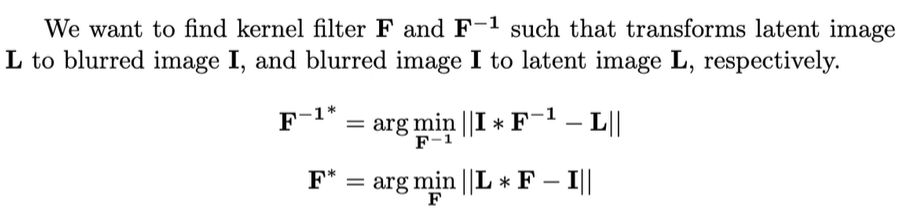

However, this method requires a significant amount of image data and typically requires the algorithm to be trained on many original and deblurred image pairs. The algorithm is trained using Bayes' Theorem, a method of estimating something called the posterior probability of the deblurring kernel given the blurred image data. Posterior probablity is an attribute of Bayesian statistics and an estimate of how probable an event (in this case, blurring characteristic) is after receiving data on similar original/blurred pairs. Essentially, the model is able to use its knowledge of typical blur characteristics and adjust its predictions based on actual blur characteristics, improving the quality of newly estimated kernels. The network learns the patterns/relationships between blurred and sharp images, which allows it to ultimately deblur the images (and estimate a deblurring kernel) more effectively. However, the model is only as good as the dataset used to train it, making it very important that the pairs of original/blurred images have relatively similar deblurring characteristics to the images the model will be used on.

2. A second method of deblurring kernel approximation is by taking the gradient difference between a pixel and the pixels surrounding it in order to determine the amount of blurring. This information is used to create a "blur map" which is then used to deblur the image using non-blind deconvolution (or essentially trying to go backwards and un-apply that deblurring kernel to the blurred image to achieve a sharper image). This study ([https://www.sciencedirect.com/science/article/pii/S2096579623000402](https://www.sciencedirect.com/science/article/pii/S2096579623000402)) details the cutting edge way that edges are detected with that blur map.

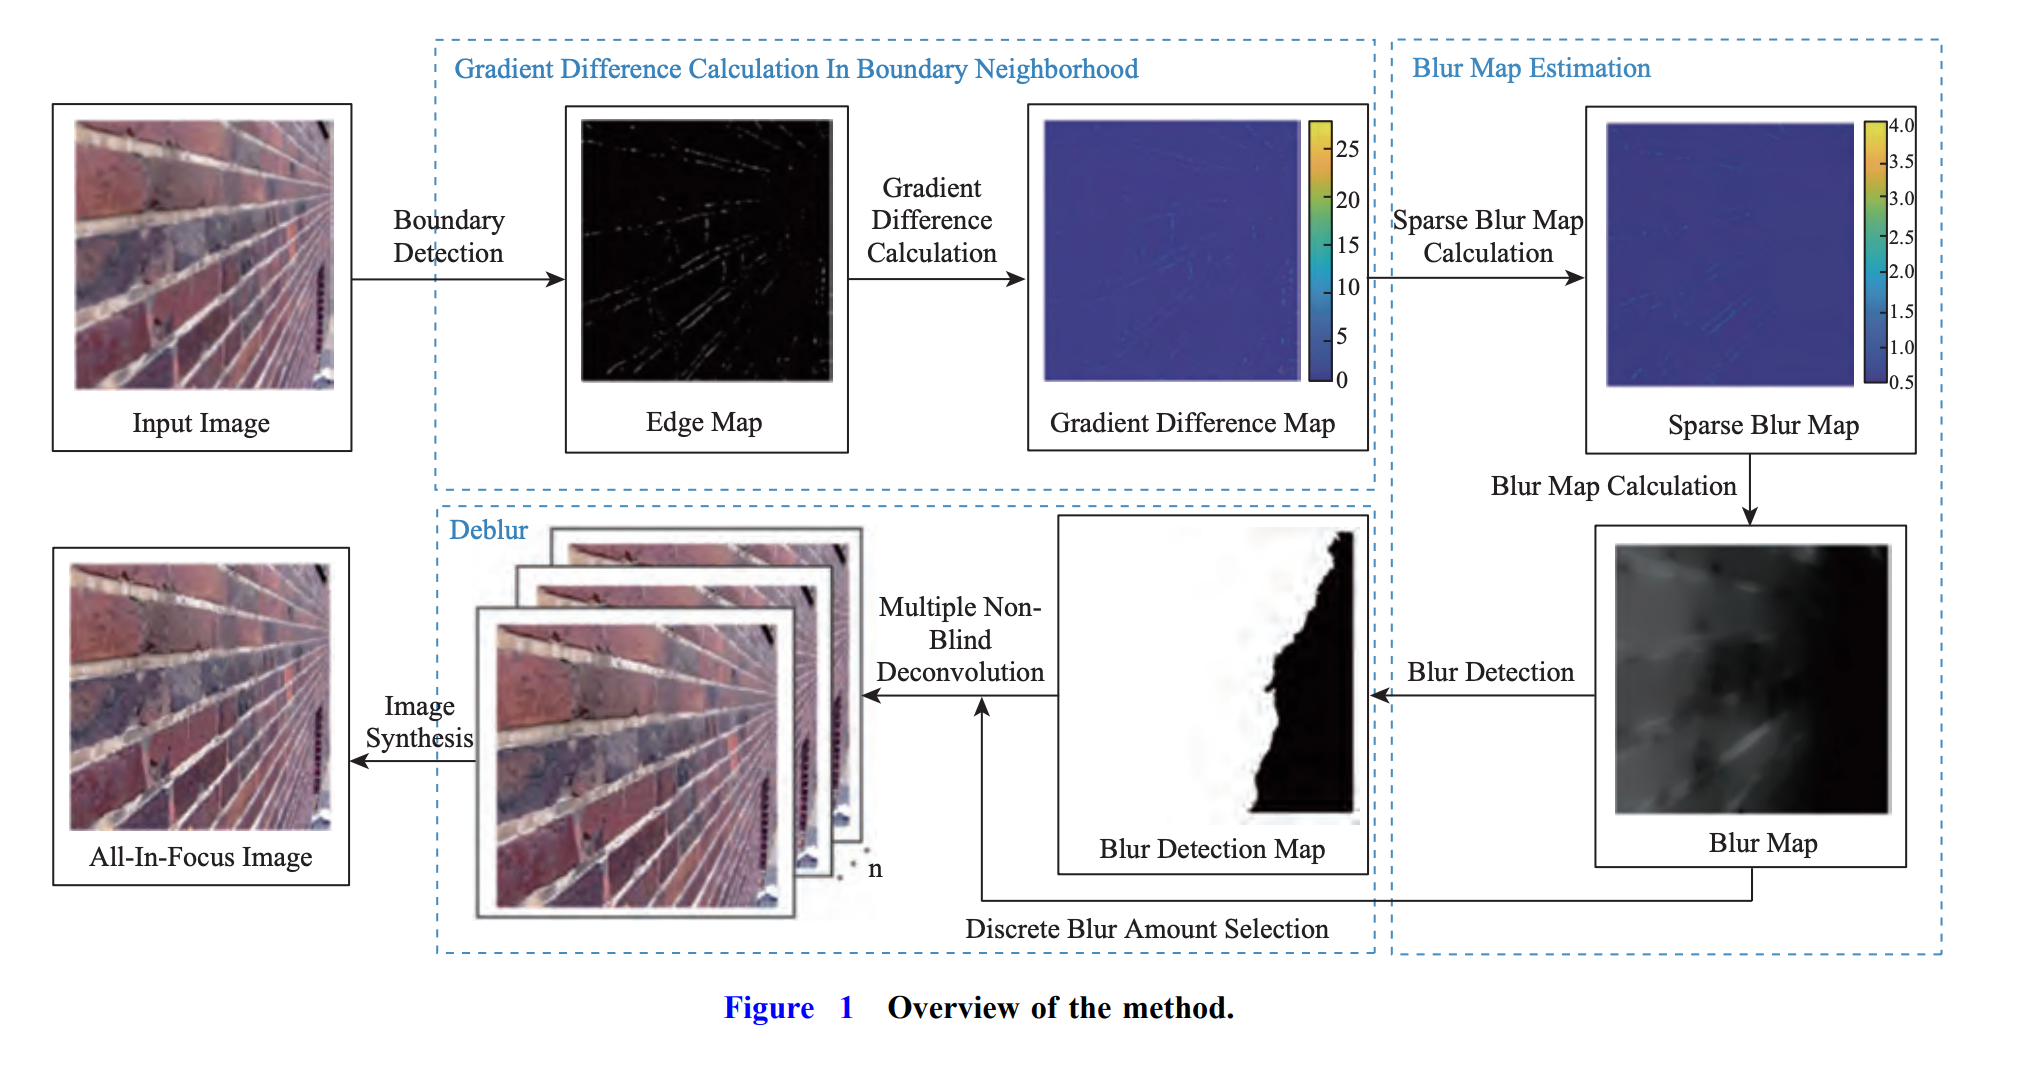

The paper details that an input image is taken and boundaries are detected. This could be done by looking at the highest frequencies in the image, but they do not explicitly specify. Then, gradients are calculated based on changes in brightness from pixel to pixel near those boundaries. Those gradient differences are used to create a "Sparse Blur Map", which essentially shows us what parts of the image have been blurred. Then, they use a technique called K-nearest neighbors, which is a machine learning technique, to fill out the rest of the blur map. That map helps them figure out what parts of the image are affected and by how much, and helps them estimate a deblurring kernel to sharpen the original image with.

Works Cited

Park, S. (2024, December 14). *Initial Kernel Estimation for Image Deblurring - Team DeFT*. YouTube. https://www.youtube.com/watch?v=4Xe0i5lpWQ4&t=230s 

TAO, J., WANG, Y., M.A, H., YAN, T., AI, L., ZHANG, S., & LI, W. (2023). Image defocus deblurring method based on gradient difference of Boundary Neighborhood. *Virtual Reality & Intelligent Hardware*, *5*(6), 538–549. https://doi.org/10.1016/j.vrih.2023.06.008 

**3. Histogram equalization. **Use histogram equalization as an image enhancement technique on two images of your choice. If you used inbuilt functions (e.g. histeq in MATLAB, or cv2.equalizeHist() in OpenCV), did you see any limitations of these inbuilt functions? If yes, what are they? **(10 points). **(sample histogram equalization code: [imenhance.m](https://canvas.olin.edu/courses/819/files/186985?wrap=1)

clear all;
close all;

i = imread("../../pictures/cat.jpeg");
i2 = imread("../../pictures/dog.png");

figure;
subplot(1, 2, 1);
imshow(i);
title('Cat Image');
subplot(1, 2, 2);
imhist(i);
title('Cat Image Histogram');

imh1 = histeq(i);

figure;
subplot(2, 2, 1);
imshow(i);
title('Cat Image');
subplot(2, 2, 2);
imhist(i);
title('Cat Image Histogram');
subplot(2, 2, 3);
imshow(imh1);
title('Histogram Equalized Cat Image');
subplot(2, 2, 4);
imhist(imh1);
title('Equalized Cat Image Histogram');

imh_stretch = imadjust(i, [0.6, 0.9], [0.0, 1.0]);
figure;
subplot(2, 2, 1);
imshow(imh_stretch);
title('Stretched Image');
subplot(2, 2, 2);
imhist(imh_stretch);
title('Stretched Image Histogram');
subplot(2, 2, 3);
imshow(imh1);
title('Histogram Equalized Image');
subplot(2, 2, 4);
imhist(imh1);
title('Equalized Image Histogram');
figure;
subplot(1, 2, 1);
imshow(i2);
title('Dog Image');
subplot(1, 2, 2);
imhist(i2);
title('Dog Image Histogram');

imh2 = histeq(i2);

figure;
subplot(2, 2, 1);
imshow(i2);
title('Dog Image');
subplot(2, 2, 2);
imhist(i2);
title('Dog Image Histogram');
subplot(2, 2, 3);
imshow(imh2);
title('Histogram Equalized Dog Image');
subplot(2, 2, 4);
imhist(imh2);
title('Equalized Dog Image Histogram');
imh_stretch = imadjust(i2, [0.6, 0.9], [0.0, 1.0]);
figure;
subplot(2, 2, 1);
imshow(imh_stretch);
title('Stretched Dog Image');
subplot(2, 2, 2);
imhist(imh_stretch);
title('Stretched Dog Image Histogram');
subplot(2, 2, 3);
imshow(imh2);
title('Histogram Equalized Dog Image');
subplot(2, 2, 4);
imhist(imh2);
title('Equalized Dog Image Histogram');

- Histogram equalization can oversaturate bright or dark regions, causing a loss of details in the image

- For images with certain intensity distributions, `histeq` might not evenly enhance all areas of the image, leading to unnatural-looking results.

**4. Some more filtering. **You are provided with a code ‘[Frequency_LPF.m](https://canvas.olin.edu/courses/819/files/186868?wrap=1)[ Download Frequency_LPF.m](https://canvas.olin.edu/courses/819/files/186868/download?download_frd=1)’). It implements 3 types of low pass filters in frequency domain – ideal, butterworth and gaussian. Run this code for an image of your choice. Comment on the effects of these filters in your image. Feel free to play around with parameters and those changes to your comments. **(10 points).**

It can be seen that the ideal filter cuts off all high frequencies in the image very abruptly. The resulting image has significantly less detail on the snow, since it is a high frequency object in the image. The edges are also obviously smoothed from the original photo, since sharp edges are high frequencies, but it still maintains the edges more so than some of the other filters. The higher the LPF frequency is, the closer the image is to the original. With a very low cutoff frequency, the image appears extremely blurry and mottled with color, since the detail is in the higher frequencies.

 The butterworth filter seems to blur the image more evenly than the ideal low pass filter, as it can be seen that the white highlights on the flowers seems somewhat more smoothed in the BLPF image than in the ILPF or original images for a u0 value of 100. This makes sense, as frequencies are slowly being excluded rather than extremely abruptly. However, all low frequencies are included as the passband is flat and then smoothly decreasing for high frequencies. For low u0 values (low cutoff frequencies) the image is significantly more intelligible than the ideal LPF  just appears evenly blurred.

The smoothest of the images is the GLPF filter. It shows the smoothest transition between high and low frequencies, as the passband is slowly decreasing from low to high in the shape of a gaussian distribution. The flowers seem the most naturally blurred using this filter as a result of the lack of sharp corners or changes in the passband. However, the butterworth and gaussian LPFs are fairly similar because they both attempt to prevent artifacts in the image by gradually excluding noise. Thus, similar to the butterworth, the gaussian filter also appears evenly smoothed and far more intelligible than the ILPF with a cutoff frequency of 10.

%% Frequency domain low pass filtering (Ideal, Butterworth and Gaussian LPF)
% code credit: https://www.abhilashsingh.net/?source=lpf_matlab
clc
clear all
%%
img = imread('../../pictures/pink_flowers.jpg');
gimg=rgb2gray(img);
subplot(331)
imshow(gimg)
title('f(x,y) (grayscaled image)')
%% Ideal low pass
P=size(gimg);
M=P(1);N=P(2);
F=fft2(gimg,M,N);
subplot(332)
%imshow(uint8(abs(fftshift(F))));
imshow(uint8(abs((F))));
title('F(u,v) (FFT of grayscaled image)') % shows frequencies in image before
u0=10; %remove freq greater than u0
u=0:(M-1);
v=0:(N-1);
idx=find(u>M/2);
u(idx)=u(idx)-M;
idy=find(v>N/2);
v(idy)=v(idy)-N;
[V,U]=meshgrid(v,u);
D=sqrt(U.^2+V.^2);
H=double(D<=u0);
% display
subplot(333)
imshow(abs(fftshift(H)),[]);
title('H(u,v) (FFT after LPF)')  % shows frequencies in image after LPF
subplot(334)
G=H.*F;
gideal=(ifft2(G));
imshow(uint8(gideal))
title('ILPF (Image After LPF)')
%% Butterworth low pass
n=1; %Butterworth filter of order n
H= 1./(1 + (D./u0).^(2*n));
subplot(335)
imshow(abs(fftshift(H)));
title('H(u,v) BLPF')
subplot(336)
G=H.*F;
gbutter=(ifft2(G));
imshow(uint8(gbutter))
title('BLPF')
%% Gaussian low pass filter
H = exp(-(D.^2)./(2*(u0^2)));
subplot(337)
imshow(abs(fftshift(H)));
title('H(u,v) GLPF')
subplot(338)
G=H.*F;
ggauss=(ifft2(G));
imshow(uint8(ggauss))
title('GLPF')

function filter = make_filter(I, radius, type)
    [rows, cols] = size(I);
    crow = round(rows/2); % Center of circle
    ccol = round(cols/2); % Center of circle
    
    % Create a meshgrid for the filter
    [x, y] = meshgrid(1:cols, 1:rows);
    distance = sqrt((x - ccol).^2 + (y - crow).^2);

    if strcmp(type, "lowpass")
        filter = double(distance <= radius);f
    elseif strcmp(type, "highpass")
        filter = double(distance > radius);
    else
        disp("Invalid Filter Type");
    end
end